#### ** Here we see the filter bank as designed by** ***C. Li, C. Zheng, and C. Tai, “Detection of ECG characteristic points using wavelet transforms,” IEEE Trans. Biomed. Eng., vol. 42, pp. 21–28, Jan. 1995"***

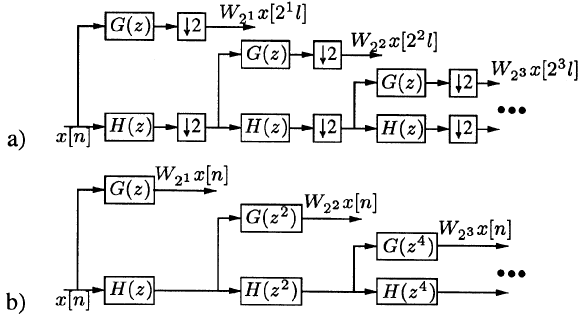

Two filter-bank implementations: a) Mallat's algorithm  b) Algorithm a trous.

Ofcourse we will utilize algorithm a trous.

We will operate on qtdb database sampled at 250Hz

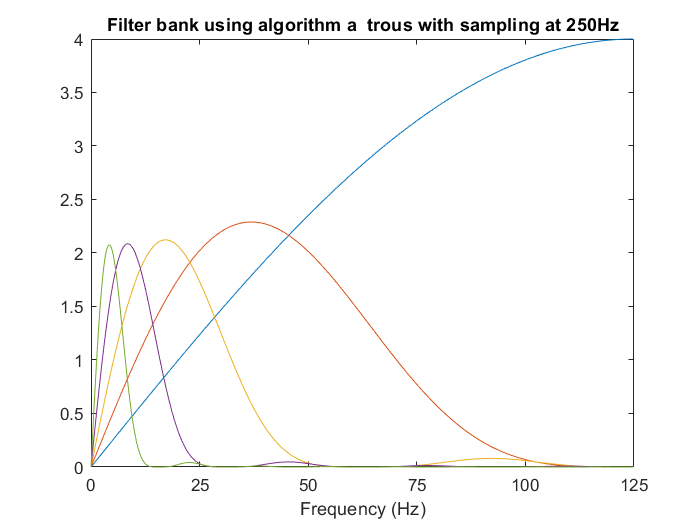

clc; clear all; close all;
fs = 250;
Gz = 2*[1 -1];
Hz = 1/8*[1 3 3 1];
level = 5;
G = {};
H = {};
G{1} = [Gz];
H{1} = [Hz];
for i = 1:level
    G{i+1} = upsample(Gz,2^i) ;
    H{i+1} = upsample(Hz,2^i) ; 
end

W{1} = G{1};
for i = 2:level
    temp = G{i};
    for j = 1:(i-1)
        temp = conv(temp , H{j});
    end
    W{i} = [temp];
end

for i = 1:(level)
    [h,q] = freqz( W{i} ,[1]);
    q = q*125/pi;
    plot(q,abs(h));
    hold on
end
title 'Filter bank using algorithm a  trous with sampling at 250Hz'
xlabel 'Frequency (Hz)'
xlim([0,125])
xticks([0,25,50,75,100,125])

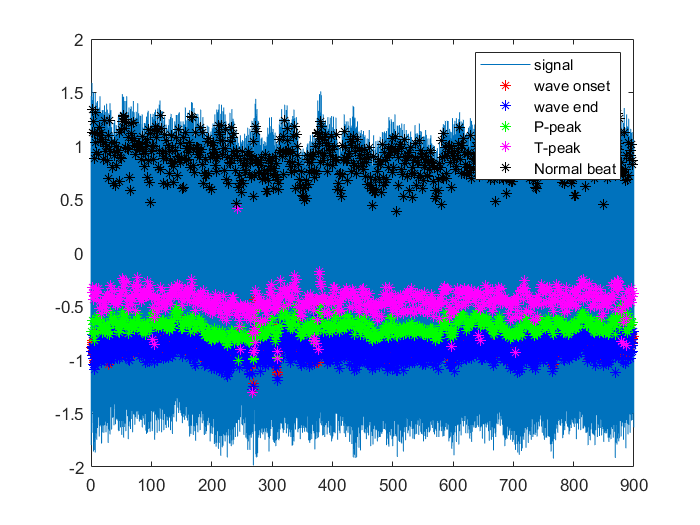

[sig, Fs, tm] = rdsamp('qtdb/sel123', 1);
[record, a] = rdann('qtdb/sel123','pu0');
figure
plot(tm,sig,tm(record(find(a=='('))),sig(record(find(a=='('))),'r*');
hold on
plot(tm(record(find(a==')'))),sig(record(find(a==')'))),'b*');
plot(tm(record(find(a=='p'))),sig(record(find(a=='p'))),'g*');
plot(tm(record(find(a=='t'))),sig(record(find(a=='t'))),'m*');
plot(tm(record(find(a=='N'))),sig(record(find(a=='N'))),'k*');
legend('signal','wave onset','wave end','P-peak','T-peak','Normal beat')

## Defining Filters

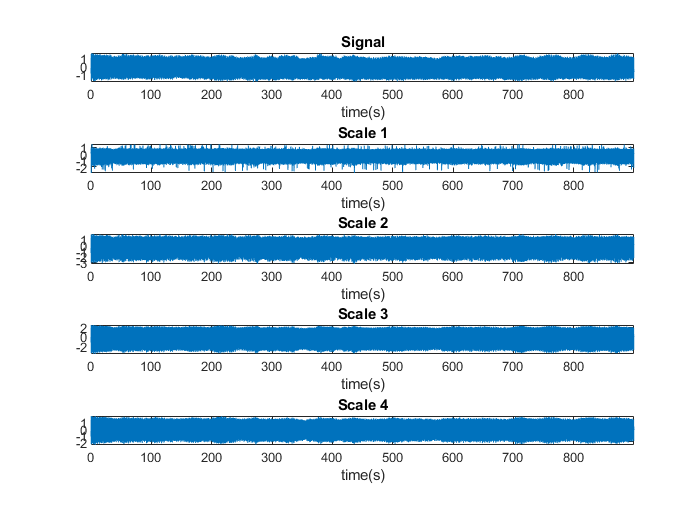

x = sig;

figure
w1=conv([0;x],W{1},'same'); % scale 2^1
w1(end)=[];
w1(1)=[];
w1=[w1;0];
w2=conv([0;0;0;0;x],W{2},'same'); % scale 2^2
w2(end-3:end)=[];
w2(1:3)=[];
w2=[w2;zeros(3,1)];
w3=conv([0;0;0;0;0;0;0;0;0;0;x],W{3},'same'); % scale 2^3
w3(end-9:end)=[];
w3(1:7)=[];
w3=[w3; zeros(7,1)];
w4=conv([zeros(22,1);x],W{4},'same'); % scale 2^4
w4(end-21:end)=[];
w4(1:15)=[];
w4=[w4;zeros(15,1)];
w5=conv(x,W{5},'same');
figure()
subplot(5,1,1)
plot(tm,x), title('Signal')
axis tight
xlabel 'time(s)'
subplot(5,1,2)
plot(tm,w1), title('Scale 1')
xlabel 'time(s)'
axis tight
subplot(5,1,3)
plot(tm,w2), title('Scale 2')
xlabel 'time(s)'
axis tight
subplot(5,1,4)
plot(tm,w3), title('Scale 3')
axis tight
xlabel 'time(s)'
subplot(5,1,5)
plot(tm,w4), title('Scale 4')
axis tight
xlabel 'time(s)'

## **Finding the positions of R peaks and QRS onsets and ends**

**Note: As our implementation did not give very good results for QRS onset and end, we have used the ground-truth annotations of QRS onset and end.**

R_peaks = record(find(a == 'N'));
QRS_end = false(size(a));
for i=1:numel(a)-1
    if a(i) == 'N' && a(i+1) == ')'
        QRS_end(i+1) = true;
    end
end
QRS_ends = record(QRS_end);
QRS_on = false(size(a));
for i=1:numel(a)-1
    if a(i) == '(' && a(i+1) == 'N'
        QRS_on(i) = true;
    end
end
QRS_ons = record(QRS_on);

## T Wave Detection and Delineation

% T wave detection and delineation
sw = (420 / 1000) * 250;
eps_T = 0.25 * rms(w4);

T1 = [];
T2 = [];
T_on = [];
T_end = [];
for i=1:numel(QRS_ends)
    if QRS_ends(i) + sw < size(w4, 1)
        gamma_T = 0.125 * max(abs(w4(QRS_ends(i) : QRS_ends(i) + sw)));
        prelim_peaks_T = [];
        max_found = false;
        for j=QRS_ends(i) : QRS_ends(i) + sw
            if abs(w4(j)) >= eps_T & abs(w4(j-1)) < abs(w4(j)) & ~max_found
                max_found = true;
            elseif max_found
                if abs(w4(j)) >= abs(w4(j-1))& abs(w4(j))>= abs(w4(j+1))
                    prelim_peaks_T = [prelim_peaks_T; j];
                    max_found = false;
                end
            end
        end
        if size(prelim_peaks_T, 1) >= 2
            significant_max = [];
            for p=1:numel(prelim_peaks_T)
                pos = prelim_peaks_T(p);
                if abs(w4(pos)) > gamma_T
                    significant_max = [significant_max; pos];
                end
            end
            if size(significant_max, 1) == 2
                [c, l] = min(abs(w3(significant_max(1):significant_max(2))));
                T1 = [T1; l + significant_max(1)];
                T2 = [T2; 0];
                n_first = significant_max(1);
                n_last = significant_max(2);
                wave_not_found = false;
            elseif size(significant_max, 1) > 2
                significant_max = significant_max(1:3);
                [m0, I0] = min(abs(w3(significant_max(1):significant_max(2))));
                T1 = [T1; I0 + significant_max(1)];
                [m1, I1] = min(abs(w3(significant_max(2):significant_max(3))));
                T2 = [T2; I1  + significant_max(2)];
                n_first = significant_max(1);
                n_last = significant_max(end);
                wave_not_found = false;
            else
                wave_not_found = true;
            end
        else
            wave_not_found = true;
        end
        
        if ~wave_not_found
            xi_T_on = 0.25 * abs(w4(n_first));
            xi_T_end = 0.4 * abs(w4(n_last));
            
            win = (80 / 1000) * 250;
            update = -1;
            search_pos = n_first + update;
            while abs(search_pos - n_first) < win & search_pos >= 1 & search_pos <= size(w4, 1) - 2
                if (abs(w4(search_pos)) < xi_T_on) || (abs(w4(search_pos)) > abs(w4(search_pos + 1))) & abs(w4(search_pos)) > abs(w4(search_pos - 1))
                    ton = search_pos;
                    break;
                else
                    search_pos = search_pos + update;
                end
            end
            T_on = [T_on; ton];
            update = 1;
            search_pos = n_last + update;
            while abs(search_pos - n_last) < win & search_pos >= 1 & search_pos <= size(w4, 1) - 2
                if (abs(w4(search_pos)) < xi_T_end) || (abs(w4(search_pos)) > abs(w4(search_pos + 1))) & abs(w4(search_pos)) > abs(w4(search_pos - 1))
                    tend = search_pos;
                    break;
                else
                    search_pos = search_pos + update;
                end
            end
            T_end = [T_end; tend];
        else
            T1 = [T1; 0];
            T2 = [T2; 0];
            T_on = [T_on; 0];
            T_end = [T_end; 0];
        end
    else
        T1 = [T1; 0];
        T2 = [T2; 0];
        T_on = [T_on; 0];
        T_end = [T_end; 0];
    end
end

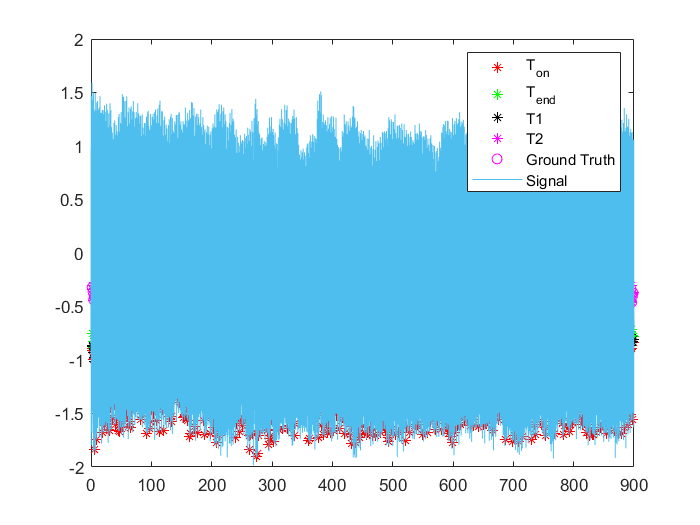

% for debugging
figure;
plot(tm(T_on(T_on ~= 0)), sig(T_on(T_on ~= 0)), 'r*');
hold on;
plot(tm(T_end(T_end ~= 0)), sig(T_end(T_end ~= 0)), 'g*');
hold on;
plot(tm(T1(T1 ~= 0)), sig(T1(T1 ~= 0)), 'k*');
hold on;
plot(tm(T2(T2 ~= 0)), sig(T2(T2 ~= 0)), 'm*');
hold on;
plot(tm(record(find(a=='t'))),sig(record(find(a=='t'))),'mo');
hold on;
plot(tm, sig);
legend('T_{on}', 'T_{end}', 'T1', 'T2', 'Ground Truth', 'Signal');

## P Wave Detection and Delineation

% P wave detection and delineation
sw = (200 / 1000) * 250;
eps_P = 0.02 * rms(w4);

P1 = [];
P2 = [];
P_on = [];
P_end = [];
for i=1:numel(QRS_ons)
    if QRS_ons(i) - sw >= 1
        gamma_P = 0.125 * max(abs(w4(QRS_ons(i) - sw : QRS_ons(i))));
        prelim_peaks_P = [];
        max_found = false;
        for j=QRS_ons(i) - sw : QRS_ons(i)
            if abs(w4(j)) >= eps_P & abs(w4(j-1)) < abs(w4(j)) & ~max_found
                max_found = true;
            elseif max_found
                if abs(w4(j)) >= abs(w4(j-1))& abs(w4(j))>= abs(w4(j+1))
                    prelim_peaks_P = [prelim_peaks_P; j];
                    max_found = false;
                end
            end
        end
        if size(prelim_peaks_P, 1) >= 2
            significant_max = [];
            for p=1:numel(prelim_peaks_P)
                pos = prelim_peaks_P(p);
                if abs(w4(pos)) > gamma_P
                    significant_max = [significant_max; pos];
                end
            end
            if size(significant_max, 1) == 2
                [c, l] = min(abs(w3(significant_max(1):significant_max(2))));
                P1 = [P1; l + significant_max(1)];
                P2 = [P2; 0];
                n_first = significant_max(1);
                n_last = significant_max(2);
                wave_not_found = false;
            elseif size(significant_max, 1) > 2
                significant_max = significant_max(1:3);
                [m0, I0] = min(abs(w3(significant_max(1):significant_max(2))));
                P1 = [P1; I0 + significant_max(1)];
                [m1, I1] = min(abs(w3(significant_max(2):significant_max(3))));
%                 P2 = [P2; I1  + significant_max(2)];
                n_first = significant_max(1);
                n_last = significant_max(end);
                wave_not_found = false;
            else
                wave_not_found = true;
            end
        else
            wave_not_found = true;
        end
        
        if ~wave_not_found
            xi_P_on = 0.5 * abs(w4(n_first));
            xi_P_end = 0.9 * abs(w4(n_last));
            
            win = (40 / 1000) * 250;
            update = -1;
            search_pos = n_first + update;
            while abs(search_pos - n_first) < win & search_pos >= 1 & search_pos <= size(w4, 1) - 2
                if (abs(w4(search_pos)) < xi_P_on) || (abs(w4(search_pos)) > abs(w4(search_pos + 1))) & abs(w4(search_pos)) > abs(w4(search_pos - 1))
                    pon = search_pos;
                    break;
                else
                    search_pos = search_pos + update;
                end
            end
            P_on = [P_on; pon];
            update = 1;
            search_pos = n_last + update;
            while abs(search_pos - n_last) < win & search_pos >= 1 & search_pos <= size(w4, 1) - 2
                if (abs(w4(search_pos)) < xi_P_end) || (abs(w4(search_pos)) > abs(w4(search_pos + 1))) & abs(w4(search_pos)) > abs(w4(search_pos - 1))
                    pend = search_pos;
                    break;
                else
                    search_pos = search_pos + update;
                end
            end
            P_end = [P_end; pend];
        else
            P1 = [P1; 0];
            P2 = [P2; 0];
            P_on = [P_on; 0];
            P_end = [P_end; 0];
        end
    else
        P1 = [P1; 0];
        P2 = [P2; 0];
        P_on = [P_on; 0];
        P_end = [P_end; 0];
    end
end

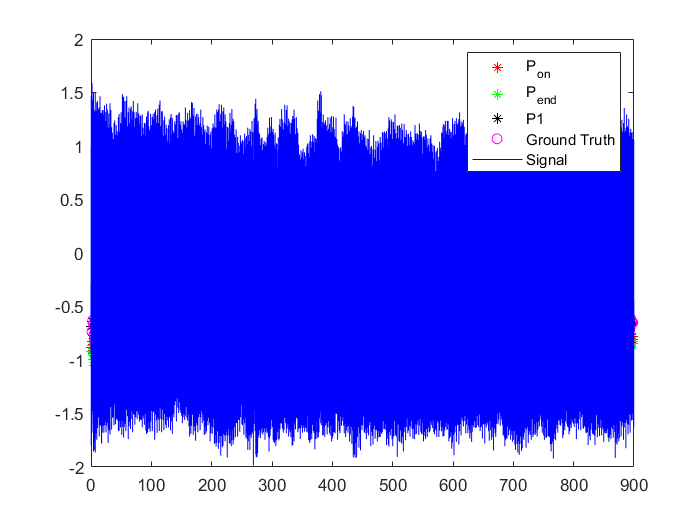

figure;
plot(tm(P_on(P_on ~= 0)), sig(P_on(P_on ~= 0)), 'r*');
hold on;
plot(tm(P_end(P_end ~= 0)), sig(P_end(P_end ~= 0)), 'g*');
hold on;
plot(tm(P1(P1 ~= 0)), sig(P1(P1 ~= 0)), 'k*');
hold on;
plot(tm(P2(P2 ~= 0)), sig(P2(P2 ~= 0)), 'm*');
hold on;
plot(tm(record(find(a=='p'))),sig(record(find(a=='p'))),'mo');
hold on;
plot(tm, sig, 'b');
legend('P_{on}', 'P_{end}', 'P1', 'Ground Truth', 'Signal');

## Predictibility Calculations

% Accuracy measurements
actual_t_peaks = record(find(a == 't'));
actual_p_peaks = record(find(a == 'p'));
matching_t1 = 0;
fp_t1 = 0;
for i=1:numel(T1)
    temp = actual_t_peaks - T1(i);
    temp_match = find(abs(temp) <= 5);
    if size(temp_match, 1) >= 1
        matching_t1 = matching_t1 + 1;
    else
        fp_t1 = fp_t1 + 1;
    end
end
matching_t2 = 0;
fp_t2 = 0;
for i=1:numel(T2)
    temp = actual_t_peaks - T2(i);
    temp_match = find(abs(temp) <= 5);
    if size(temp_match, 1) >= 1
        matching_t2 = matching_t2 + 1;
    else
        fp_t2 = fp_t2 + 1;
    end
end

matching_p1 = 0;
fp_p1 = 0;
for i=1:numel(P1)
    temp = actual_p_peaks - P1(i);
    temp_match = find(abs(temp) <= 5);
    if size(temp_match, 1) >= 1
        matching_p1 = matching_p1 + 1;
    else
        fp_p1 = fp_p1 + 1;
    end
end
matching_p2 = 0;
fp_p2 = 0;
for i=1:numel(P2)
    temp = actual_p_peaks - P2(i);
    temp_match = find(abs(temp) <= 5);
    if size(temp_match, 1) >= 1
        matching_p2 = matching_p2 + 1;
    else
        fp_p2 = fp_p2 + 1;
    end
end
fprintf('Predictivity of T wave peak detection: %.5f %% \n', 100 * max(matching_t1 / (matching_t1 + fp_t1), matching_t2 / (matching_t2 + fp_t2)));

Predictivity of T wave peak detection: 98.26897 % 


fprintf('Predictivity of P wave peak detection: %.5f %% \n', 100 * max(matching_p1 / (matching_p1 + fp_p1), matching_p2 / (matching_p2 + fp_p2)));

Predictivity of P wave peak detection: 99.33422 % 
